# Weiner Filtering

## Data Construction


load("idealECG.mat");

gaussian_10 = awgn(idealECG,10,'measured'); % Gaussian noise of 10 dB

fs = 500; % Sampling Rate
time = (0:length(idealECG)-1)/fs; % Time array
n = 1:length(idealECG); % Samples array

sin_50 = 0.2 .* sin(2*pi*50*time); 
noise = (gaussian_10-idealECG) + sin_50; % Total noise added

input_signal = sin_50 + gaussian_10; % Input signal with added noise

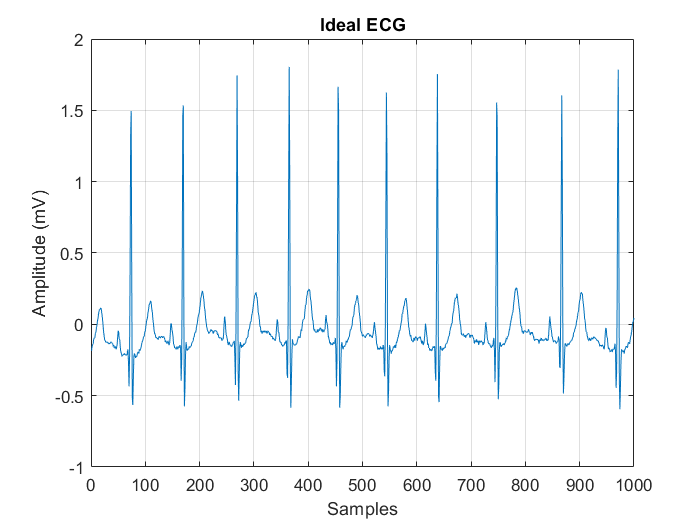

figure;

plot(n(1:1000), idealECG(1:1000));
title('Ideal ECG');
xlabel('Samples');
ylabel('Amplitude (mV)');
grid on;

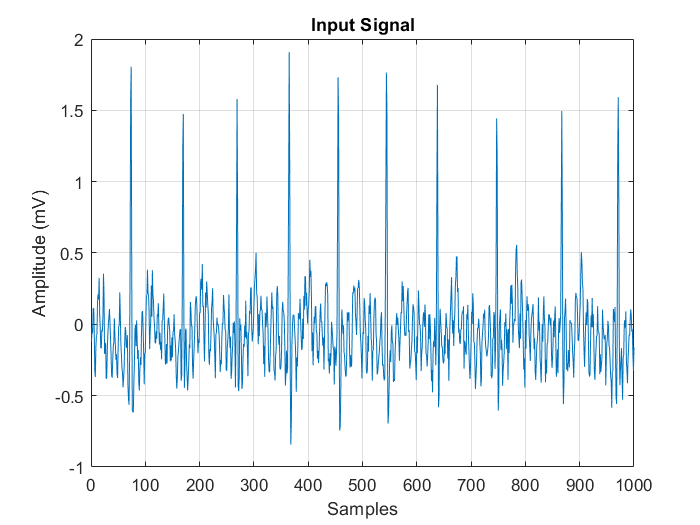

figure;

plot(n(1:1000), input_signal(1:1000));
title('Input Signal');
xlabel('Samples');
ylabel('Amplitude (mV)');
grid on;

% Extracting a single template

idealECG_template = idealECG(40:139);

Y_n_i = idealECG_template - mean(idealECG_template); % Mean removal for Wiener Filtering

noise_signal_ = input_signal(317:336); % Extract noise from T wave to P wave
noise_signal = [noise_signal_ noise_signal_ noise_signal_ noise_signal_ noise_signal_];

N_n_i = noise_signal - mean(noise_signal);  % Mean removal for Weiner Filtering


n_i = 1:length(Y_n_i); 
time_i = (0:(length(Y_n_i)-1))/500; % time signal for the single beat

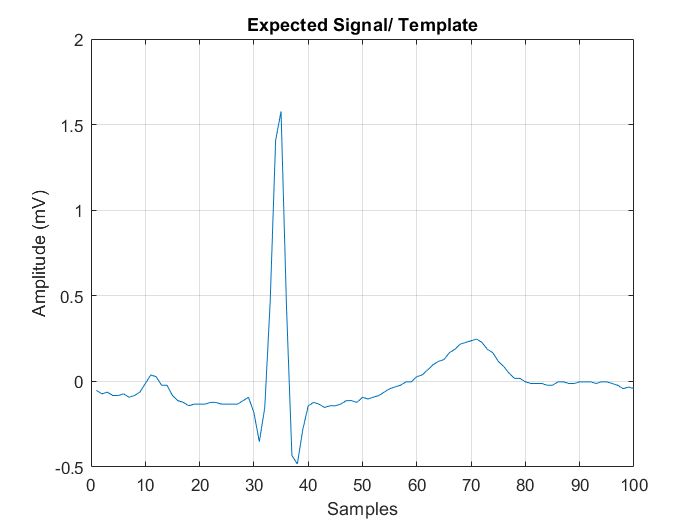

plot(n_i, Y_n_i);
title('Expected Signal/ Template');
xlabel('Samples');
ylabel('Amplitude (mV)');
grid on;

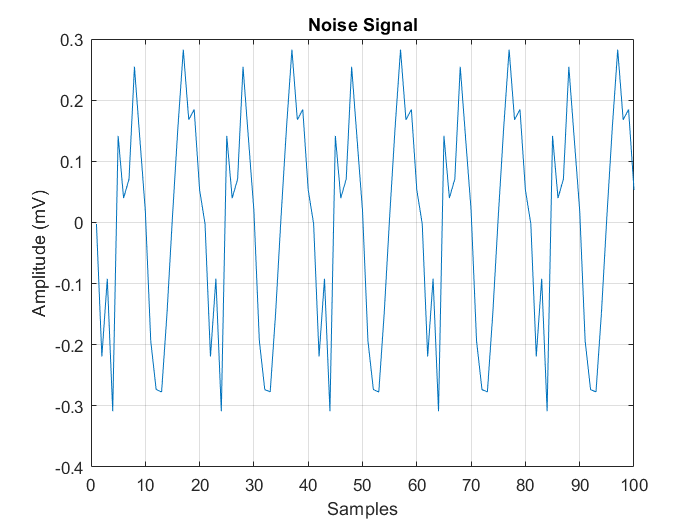

figure;

plot(n_i, N_n_i);
title('Noise Signal');
xlabel('Samples');
ylabel('Amplitude (mV)');
grid on;

## 1.1 Discrete time-domain implementation of the Weiner Filter

### Part 1

order = 25;
W0 = wienercoefs(Y_n_i, N_n_i, order); % Calculate Weiner filter coefficients

in_signal = input_signal - mean(input_signal); % Mean removal for Weiner filtering

Y_hat_n = filter(W0, 1, in_signal); % Filtered Signal

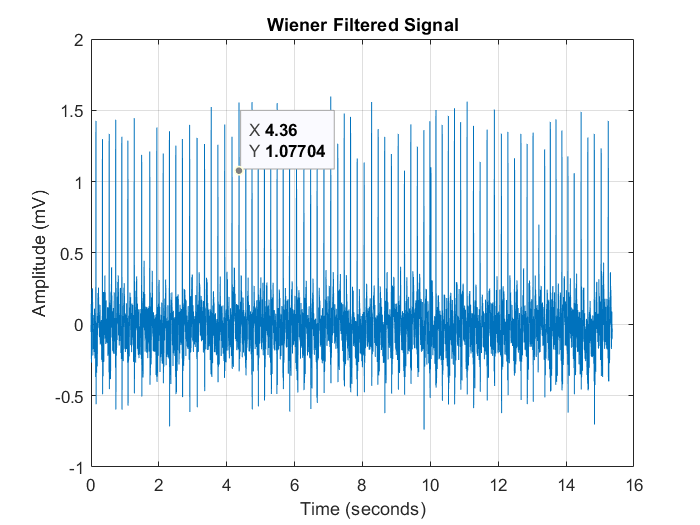

figure;

plot(time, Y_hat_n);
title('Wiener Filtered Signal');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on;


mse_wiener_25 = mse(Y_hat_n, idealECG - mean(idealECG)); % Mean square error for order 25
disp(['MSE: ',num2str(mse_wiener_25)]);

MSE: 0.012794


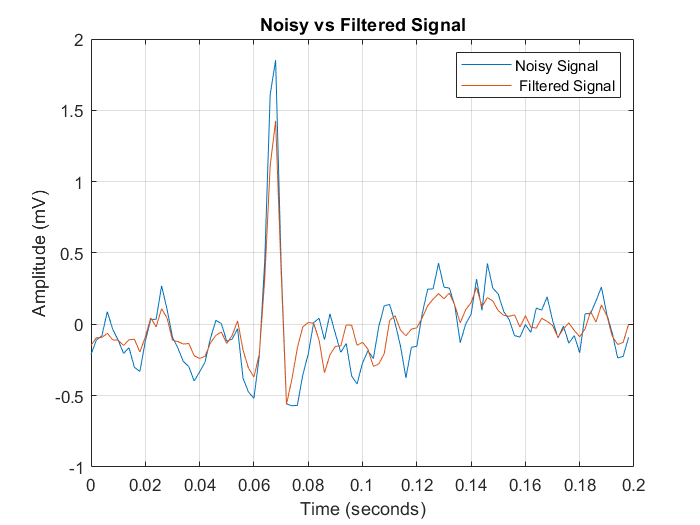

figure;

plot(time_i, in_signal(40:139));
hold on;

plot(time_i, Y_hat_n(40:139));

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Filtered Signal');
title('Noisy vs Filtered Signal')
grid on;

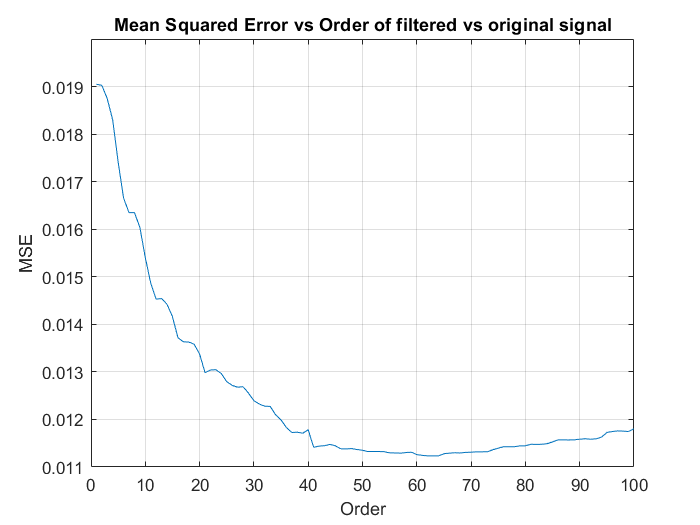

% Calculate optimum order for weiner filtering the signal

mse_wiener_array = [];

for order_i = 1:100
    W_i = wienercoefs(Y_n_i, N_n_i, order_i);
    Y_hat_n_order_i = filter(W_i, 1, in_signal);
    mse_wiener_i = mse(Y_hat_n_order_i, (idealECG - mean(idealECG)));
    mse_wiener_array = [mse_wiener_array, mse_wiener_i];
end

figure;
plot(1:100, mse_wiener_array);
title('Mean Squared Error vs Order of filtered vs original signal');
xlabel('Order');
ylabel('MSE');
grid on;

[min_mse_weiner,min_weiner_idx] = min(mse_wiener_array);
disp(['Optimum order for Weiner filter: ',num2str(min_weiner_idx)]);

Optimum order for Weiner filter: 62


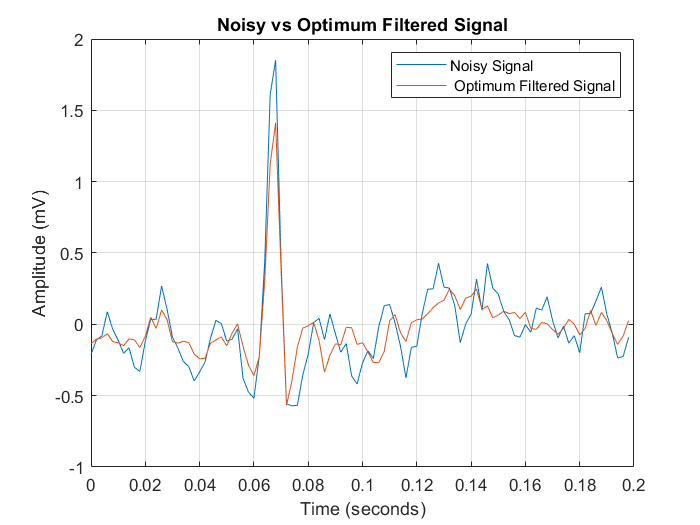

% Plotting and visualizing the impact of optimum order Weiner filtering.

optimum_order = min_weiner_idx;

W_opt = wienercoefs(Y_n_i, N_n_i, optimum_order);
Y_hat_n_opt = filter(W_opt, 1, in_signal);

figure;

plot(time_i, in_signal(40:139));
hold on;

plot(time_i, Y_hat_n_opt(40:139));

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Optimum Filtered Signal');
title('Noisy vs Optimum Filtered Signal')
grid on;

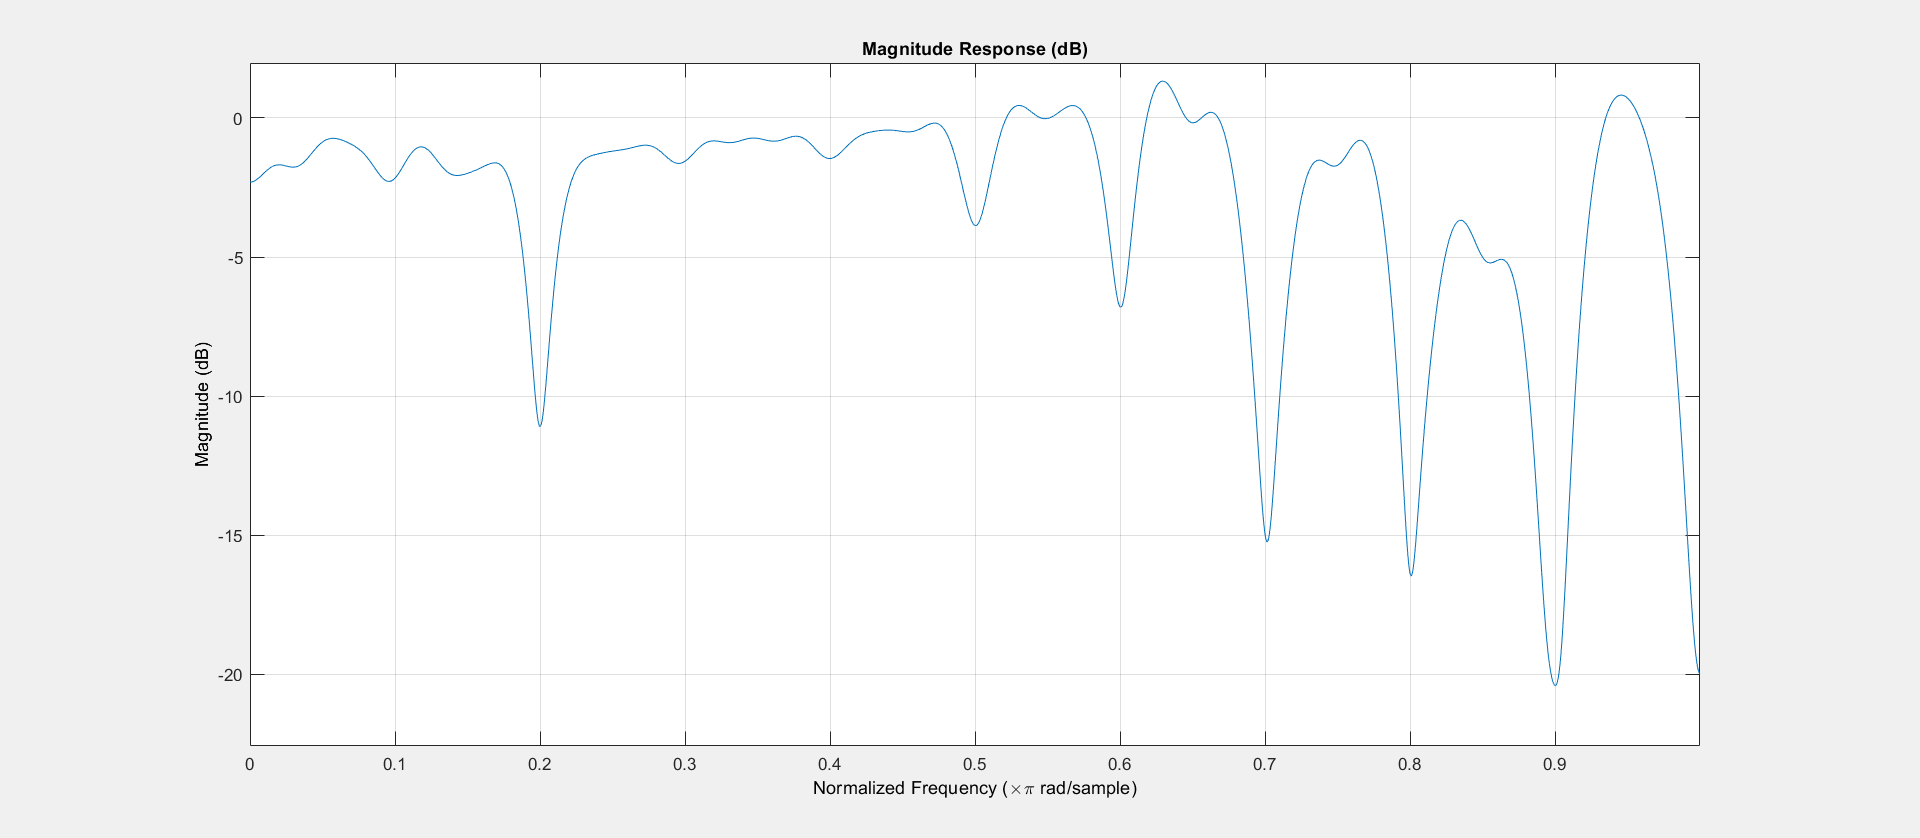

fvtool(W_opt,1);

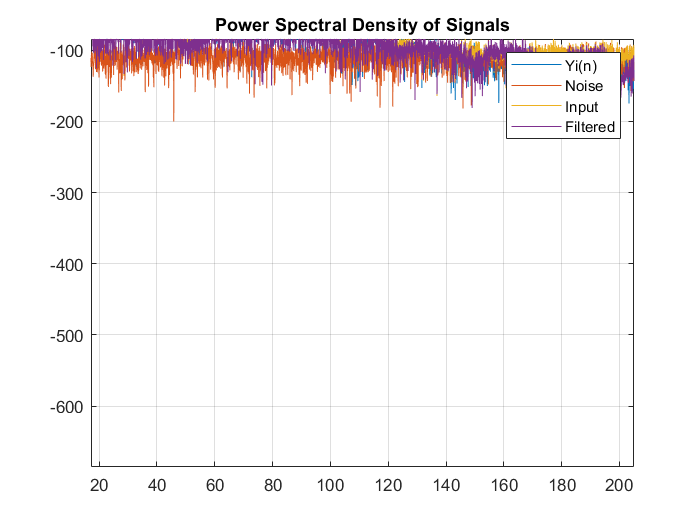

% Visualizing periodograms

figure;

[fft_Y_i, freq] = periodogram(idealECG-mean(idealECG), [], [], fs);
[fft_N_i, ~] = periodogram(noise-mean(noise), [], [], fs);
[fft_in, ~] = periodogram(in_signal, [], [], fs);
[fft_Y_hat_n, ~] = periodogram(Y_hat_n_opt, [], [], fs);

% Customize the plot

plot(freq, 10*log(fft_Y_i), freq, 10*log(fft_N_i), freq, 10*log(fft_in), freq, 10*log(fft_Y_hat_n)); 
legend('Yi(n)', 'Noise','Input','Filtered');
title('Power Spectral Density of Signals');
grid on;
hold off;

### Part 2

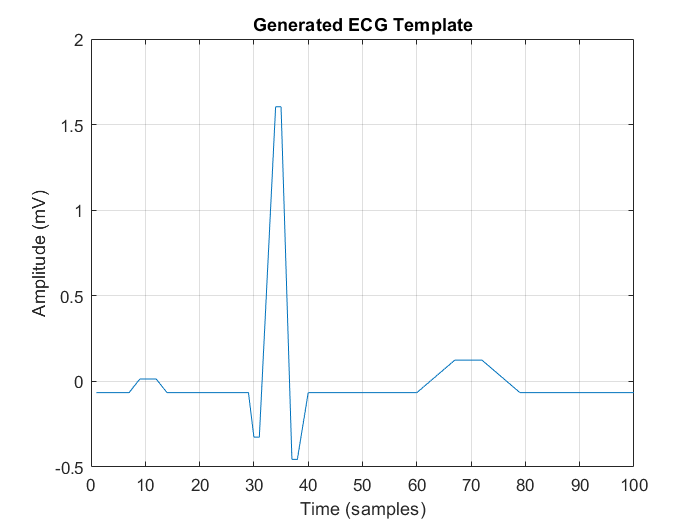

% Constructing ECG  

% Points defining the ECG segments

P_start = [6,0];
P_peak_1 = [9,0.08];
P_peak_2 = [11, 0.08];
P_end = [14,0];

Q_start = [28, 0]; 
Q_peak = [30, -0.26]; 
R_peak = [34, 1.67];  
S_peak = [37,-0.39]; 
S_end = [40,0]; 

T_start = [59,0]; 
T_peak_1 = [67,0.19]; 
T_peak_2 = [71,0.19];
T_end = [79,0];


% Create the ECG template

% P-wave (P_start to P_end)
ecg1 = zeros(1, P_start(1)); % Signal is 0 before P_start
ecg2 = linspace(P_start(2), P_peak_1(2), P_peak_1(1) - P_start(1)); % P_start to P_peak_1
ecg3 = linspace(P_peak_1(2), P_peak_2(2), P_peak_2(1) - P_peak_1(1)); % P_peak_1 to P_peak_2
ecg4 = linspace(P_peak_2(2), P_end(2), P_end(1) - P_peak_2(1)); % P_peak_2 to P_end

% QRS complex (Q_start to S_end)
ecg5 = linspace(Q_start(2), Q_peak(2), Q_peak(1) - Q_start(1)); % Q_start to Q_peak
ecg6 = linspace(Q_peak(2), R_peak(2), R_peak(1) - Q_peak(1));   % Q_peak to R_peak
ecg7 = linspace(R_peak(2), S_peak(2), S_peak(1) - R_peak(1));   % R_peak to S_peak
ecg8 = linspace(S_peak(2), S_end(2), S_end(1) - S_peak(1));     % S_peak to S_end

% T-wave (T_start to T_end)
ecg9 = linspace(T_start(2), T_peak_1(2), T_peak_1(1) - T_start(1)); % T_start to T_peak_1
ecg10 = linspace(T_peak_1(2), T_peak_2(2), T_peak_2(1) - T_peak_1(1)); % T_peak_1 to T_peak_2
ecg11 = linspace(T_peak_2(2), T_end(2), T_end(1) - T_peak_2(1)); % T_peak_2 to T_end

% Combine all the parts to form the full ECG signal
ecg_signal = [ecg1, ecg2, ecg3, ecg4, ...
              zeros(1, Q_start(1) - P_end(1)), ...
              ecg5, ecg6, ecg7, ecg8, ...
              zeros(1, T_start(1) - S_end(1)), ...
              ecg9, ecg10, ecg11, ...
              zeros(1,100-T_end(1))];
ECG_signal = ecg_signal-mean(ecg_signal); % Mean removal for Weiner filtering

% Plot the generated ECG template

n = 1:length(ECG_signal);
figure;
plot(n, ECG_signal);
title('Generated ECG Template');
xlabel('Time (samples)');
ylabel('Amplitude (mV)');
grid on;

Y_n_i_2 = ECG_signal; % The template signal

n_i = 1:length(Y_n_i_2);
time_i = (0:length(Y_n_i_2)-1)/500; 

order = 25; % Perform Weiner filtering
W0 = wienercoefs(Y_n_i_2, N_n_i, order);

Y_hat_n_2 = filter(W0, 1, in_signal); % Filtering the signal

mse_wiener_25 = mse(Y_hat_n_2, idealECG - mean(idealECG)); % Calculating Mean Squared Error

disp(['MSE with created template: ',num2str(mse_wiener_25)]);

MSE with created template: 0.01303


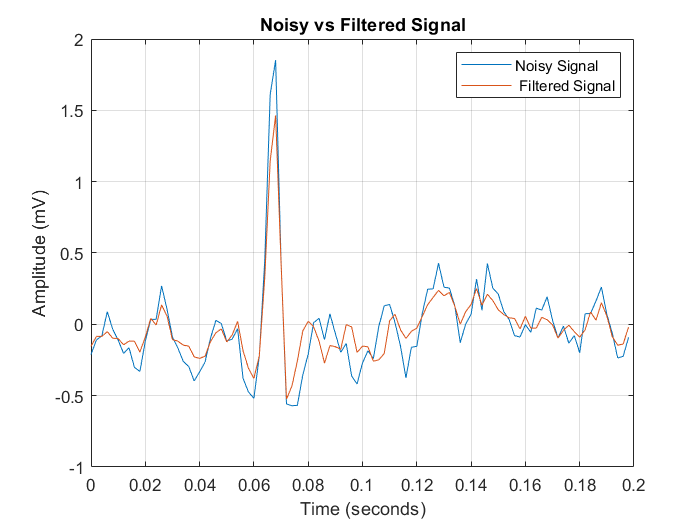

figure;

plot(time_i, in_signal(40:139));
hold on;

plot(time_i, Y_hat_n_2(40:139));

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Filtered Signal');
title('Noisy vs Filtered Signal')
grid on;

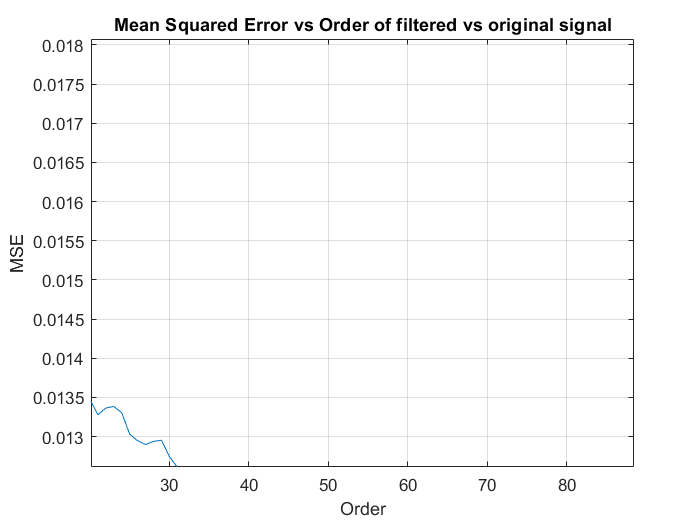

mse_wiener_array_2 = []; % Calculating optimum order

for order_i = 1:100
    W_i = wienercoefs(Y_n_i_2, N_n_i, order_i);
    Y_hat_n_order_i = filter(W_i, 1, in_signal);
    mse_wiener_i = mse(Y_hat_n_order_i, (idealECG - mean(idealECG)));
    mse_wiener_array_2 = [mse_wiener_array_2, mse_wiener_i];
end

figure;
plot(1:100, mse_wiener_array_2);
title('Mean Squared Error vs Order of filtered vs original signal');
xlabel('Order');
ylabel('MSE');
grid on;

[min_mse_weiner_2,min_weiner_idx_2] = min(mse_wiener_array_2);
disp(['Optimum order for Weiner filter with constructed ECG: ',num2str(min_weiner_idx_2)]);

Optimum order for Weiner filter with constructed ECG: 61


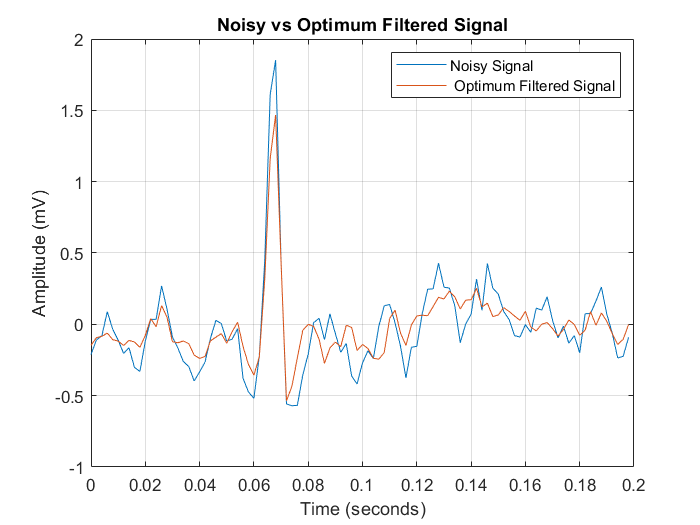

% Plotting and visualizing the impact of optimum order Weiner filtering.

optimum_order = min_weiner_idx_2;

W_opt_2 = wienercoefs(Y_n_i_2, N_n_i, optimum_order);
Y_hat_n_opt_2 = filter(W_opt_2, 1, in_signal);

figure;

plot(time_i, in_signal(40:139));
hold on;

plot(time_i, Y_hat_n_opt_2(40:139));

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Optimum Filtered Signal');
title('Noisy vs Optimum Filtered Signal')
grid on;

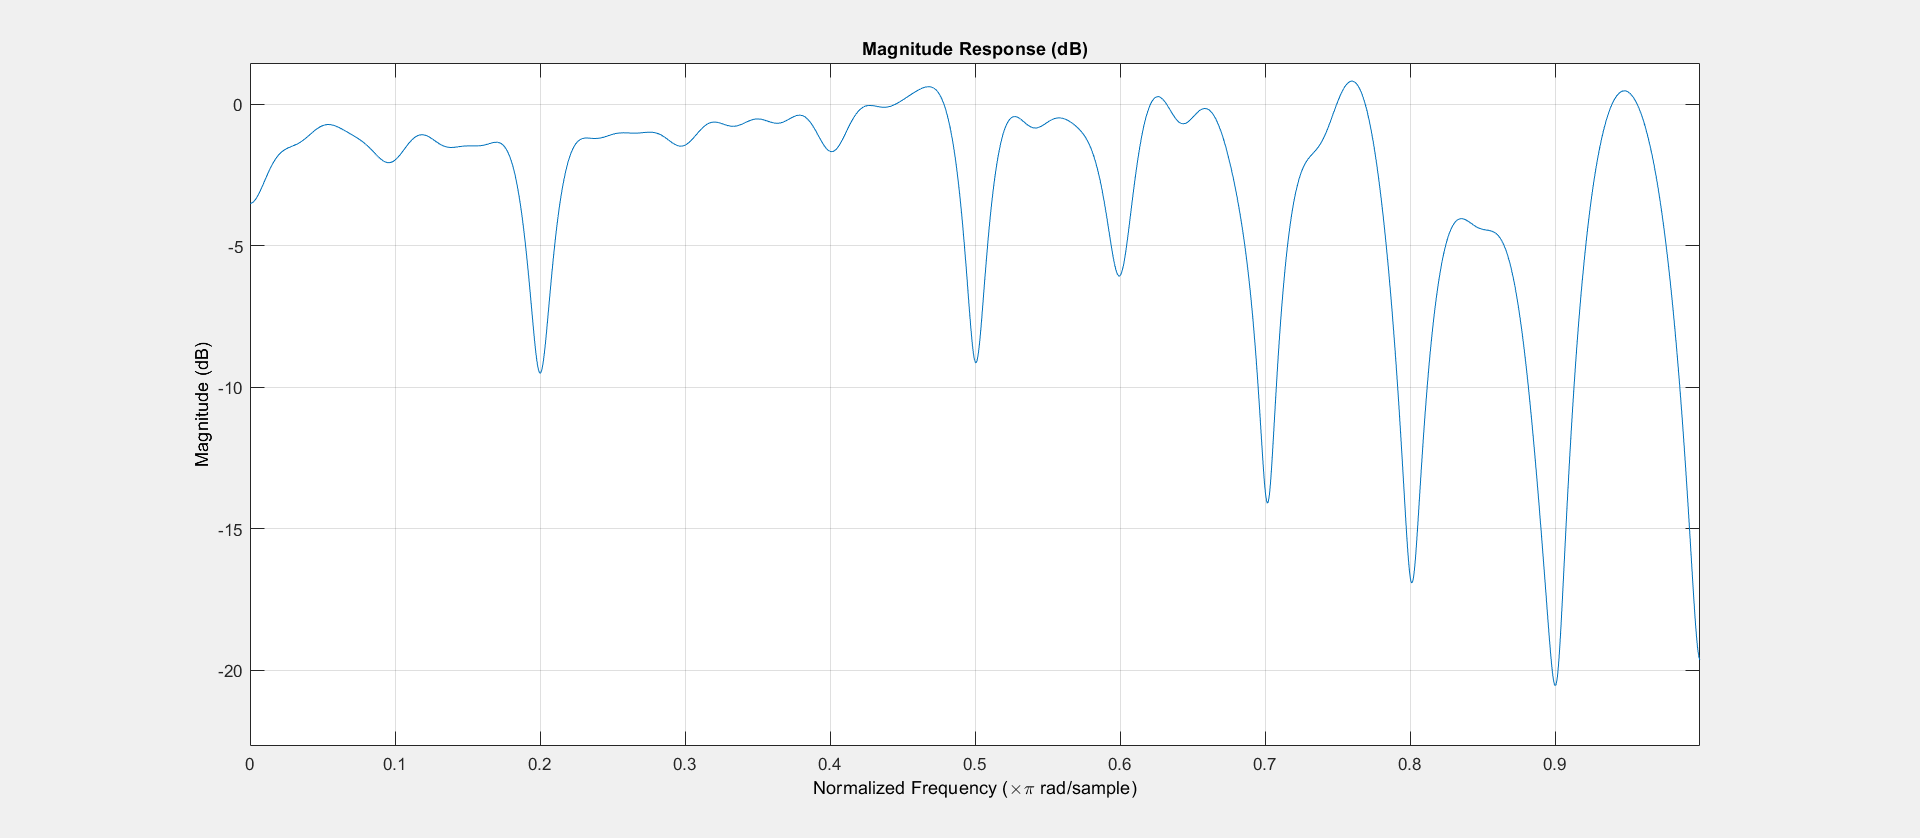

fvtool(W_opt_2,1);

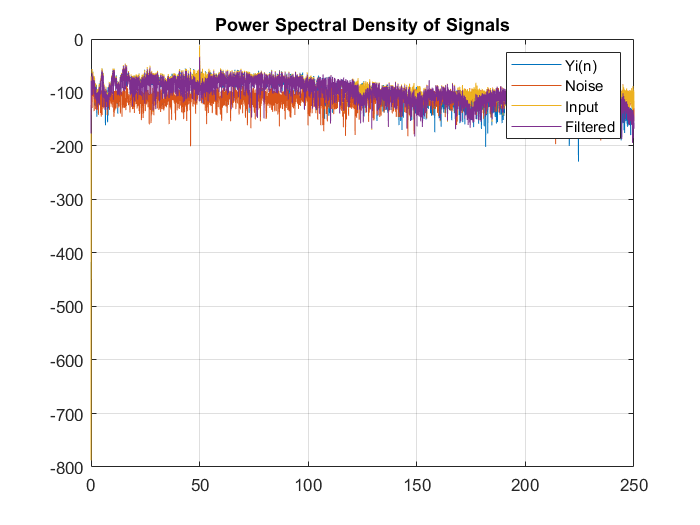

% Plot periodograms

[fft_Y_i, freq] = periodogram(idealECG-mean(idealECG), [], [], fs);
[fft_N_i, ~] = periodogram(noise, [], [], fs);
[fft_in, ~] = periodogram(in_signal, [], [], fs);
[fft_Y_hat_n_2, ~] = periodogram(Y_hat_n_opt_2, [], [], fs);

% Customize the plot

figure;
plot(freq, 10*log(fft_Y_i), freq, 10*log(fft_N_i), freq, 10*log(fft_in), freq, 10*log(fft_Y_hat_n_2)); 
legend('Yi(n)', 'Noise','Input','Filtered');
title('Power Spectral Density of Signals');
grid on;
hold off;

## 1.2 Frequency domain implementation of the Wiener filter

#### Case 1

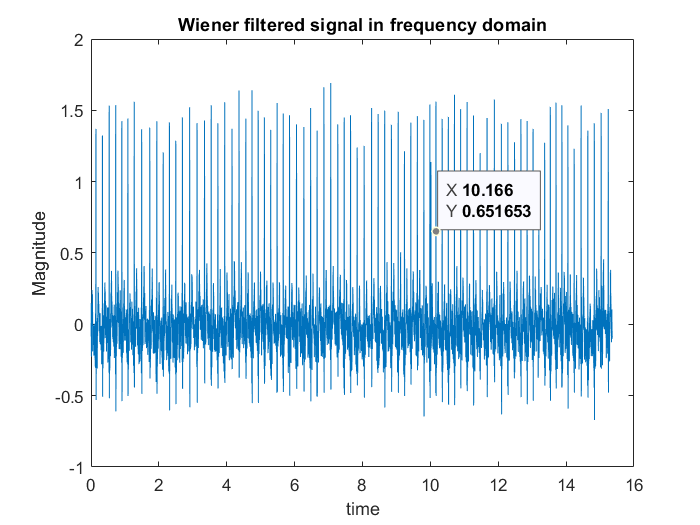

length_x = length(in_signal);

S_yy = abs(fft(Y_n_i,2*length_x-1)).^2; % PSD of template ECG
S_nn = abs(fft(N_n_i,2*length_x-1)).^2; % PSD of characterized noise
S_xx = fft(in_signal,2*length_x-1); % PSD of input signal

W_f = S_yy./(S_yy+S_nn);

S_yy_hat = W_f.*S_xx; % Filtered in freq domain

filtered_wiener_f_ = ifft(S_yy_hat); % Inverse fft to reconstruct signal
filtered_wiener_f = filtered_wiener_f_(1:length_x); % Taking half the mirror image

figure;
plot(time, filtered_wiener_f);
xlabel('time');
ylabel('Magnitude');
title('Wiener filtered signal in frequency domain')


% Calculating MSE

mse_wiener_f_1 = mse(filtered_wiener_f, idealECG-mean(idealECG))

mse_wiener_f_1 = 0.0082

#### Case 2

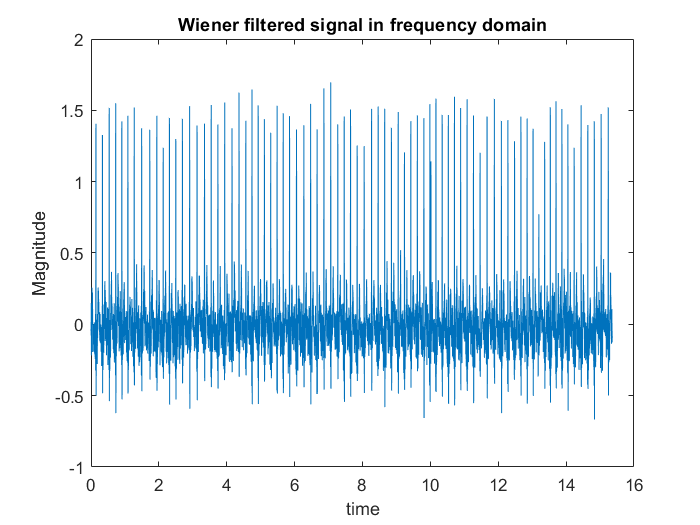


S_yy_2 = abs(fft(Y_n_i_2,2*length_x-1)).^2; % PSD of template ECG
W_f_2 = S_yy_2./(S_yy_2+S_nn); 

S_yy_hat_2 = W_f_2.*S_xx; % Filtered in freq domain

filtered_wiener_f_2_ = ifft(S_yy_hat_2); % Inverse fft to reconstruct signal
filtered_wiener_f_2 = filtered_wiener_f_2_(1:length_x); % Taking half the mirror image

figure;
plot(time, filtered_wiener_f_2);
xlabel('time');
ylabel('Magnitude');
title('Wiener filtered signal in frequency domain')


mse_wiener_f_2 = mse(filtered_wiener_f_2, idealECG-mean(idealECG))

mse_wiener_f_2 = 0.0083

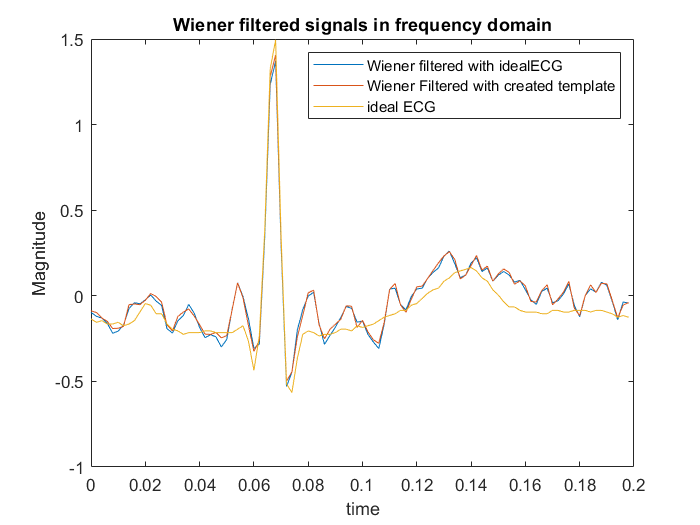

figure;
plot(time_i, filtered_wiener_f(40:139));
hold on;

plot(time_i, filtered_wiener_f_2(40:139));
hold on;

plot(time_i, idealECG(40:139));

legend('Wiener filtered with idealECG','Wiener Filtered with created template','ideal ECG')
xlabel('time');
ylabel('Magnitude');
title('Wiener filtered signals in frequency domain')

## 1.3  Effect on non-stationary noise on Wiener filtering

% Data Construction

sin_100 = 0.2 .* sin(2*pi*100*time);

input_signal_2 = nan(1,length(gaussian_10));
input_signal_2(1:length(gaussian_10)/2) = gaussian_10(1:length(gaussian_10)/2) + sin_50(1:length(gaussian_10)/2);
input_signal_2(length(gaussian_10)/2+1:end) = gaussian_10(length(gaussian_10)/2+1:end) + sin_100(length(gaussian_10)/2+1:end);

in_signal_2 = input_signal_2 - mean(input_signal_2);

% Filtering 
Y_hat_n_3 = filter(W_opt_2, 1, in_signal_2);

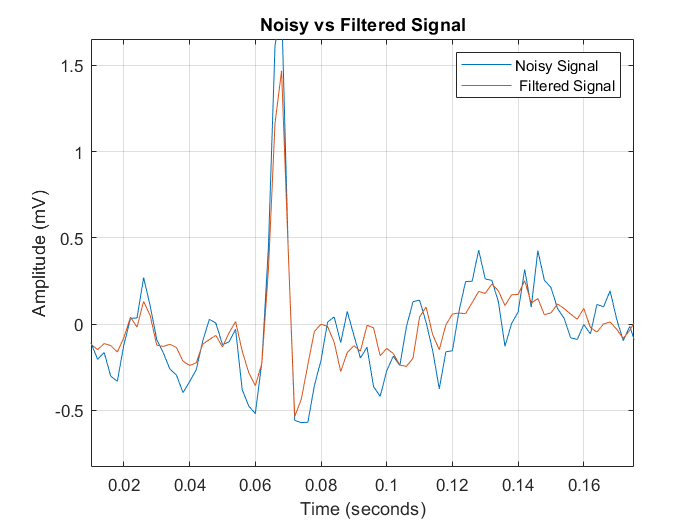

% Plotting the effect

figure;

plot(time_i, in_signal_2(40:139));
hold on;

plot(time_i, Y_hat_n_3(40:139));

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Filtered Signal');
title('Noisy vs Filtered Signal')
grid on;

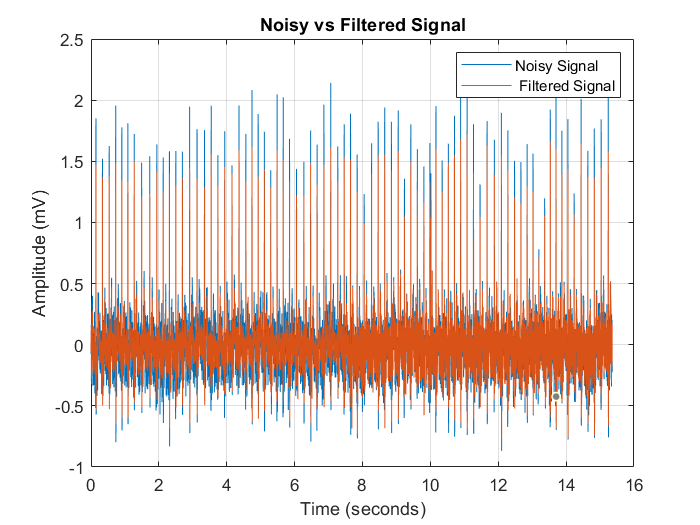

% Plotting the effect

figure;

plot(time, in_signal_2);
hold on;

plot(time, Y_hat_n_3);

xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

legend('Noisy Signal',' Filtered Signal');
title('Noisy vs Filtered Signal')
grid on;